load('C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map_data4.mat')
map = Map;
load ("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map4.mat")
Map = occupancyMap(omap);

Data

Data =           5.00          8.00
          6.00          8.00
          7.00          8.00
          8.00          8.00
          9.00          8.00
          9.96          8.24
         10.71          8.96
         11.28          9.84
         11.85         10.72
         12.42         11.60



ss = stateSpaceSE2

ss =   stateSpaceSE2 with properties:

                 Name: 'SE2'
          StateBounds: [3×2 double]
    NumStateVariables: 3.00
             WeightXY: 1.00
          WeightTheta: 0.10


ss.StateBounds

ans =        -100.00        100.00
       -100.00        100.00
         -3.14          3.14


ss.StateBounds = [[0 50]; [0 50]; [-3.1416 3.1416]];
sv = validatorOccupancyMap(ss);



sv.Map = Map

sv =   validatorOccupancyMap with properties:

                   Map: [1×1 occupancyMap]
            StateSpace: [1×1 stateSpaceSE2]
             XYIndices: [1.00 2.00]
    ValidationDistance: Inf


sv.ValidationDistance = 0.0001

sv =   validatorOccupancyMap with properties:

                   Map: [1×1 occupancyMap]
            StateSpace: [1×1 stateSpaceSE2]
             XYIndices: [1.00 2.00]
    ValidationDistance: 0.00


ss.StateBounds = [Map.XWorldLimits;Map.YWorldLimits;[-pi pi]];

rng(100, 'twister');
tic
planner = plannerRRT(ss,sv,MaxConnectionDistance=2);
[pathObj, solvInf] = plan(planner, robot_pose, goal_pose)   

pathObj =   navPath with properties:

      StateSpace: [1×1 stateSpaceSE2]
          States: [12×3 double]
       NumStates: 12.00
    MaxNumStates: Inf


solvInf = struct with fields:
      IsPathFound: 1
         ExitFlag: 1.00
         NumNodes: 37.00
    NumIterations: 59.00
         TreeData: [113×3 double]


toc

Elapsed time is 0.103001 seconds.


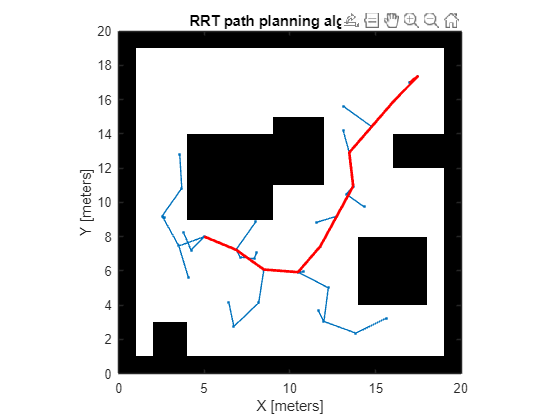


show(Map)
hold on
% Tree expansion
plot(solvInf.TreeData(:,1),solvInf.TreeData(:,2),'.-')
% Draw path
plot(pathObj.States(:,1),pathObj.States(:,2),'r-','LineWidth',2)
title("RRT path planning algorithm")

%xlabel("X [méter]")
%ylabel("Y [méter]")
pathObj.States(:,1)

ans =           5.00
          6.85
          8.47
         10.47
         11.77
         12.73
         13.69
         13.46
         14.77
         16.08


pathObj.States(:,2)

ans =           8.00
          7.23
          6.08
          5.93
          7.44
          9.19
         10.95
         12.91
         14.42
         15.94


[m,systemview] = memory;
sprintf('%.0f MB',m.MemUsedMATLAB/(1024^2))

ans = '4455 MB'